# Covid classification - CNN

remove previous data

close all; clc; clear;

choose gpu

gpu_selected = "0"; % "0" | "1" | "no"
select_gpu(gpu_selected);

gpu 0


Create audioDatastore objects of the data and split it into train, validation and test sets

dataset_name = "voca"; % "all_ds" | "voca" | "voca_old" | "coughvid"
split_prcnts = [0.6 0.2 0.2]; % size of train val test in [%]
shuffle_datasets = "yes"; % "all" | "train_val" | "no"

% load data and split to train val test
[adsTrain, adsVal, adsTest] = load_split_shuffle_datasets(dataset_name, split_prcnts, shuffle_datasets);

choose hyper-parameters

% win & spectrogram length/overlap info
win_info.win_len = 128;
win_info.overlap_coeff_win = 0.5;
win_info.overlap_coeff_spectrograms = 0.75;

% win & spectrogram normalization info
SpectrumType = "power"; % "power" "magnitude"
WindowNormalization = false; % true false
FilterBankNormalization = "none"; % "area" "bandwidth" "none"

% CNN
net_cnn_name = "vggish";
freeze_layers = "no";

% training options
MaxEpochs = 30;
miniBatchSize = 32;
InitialLearnRate = 0.0001;
L2Regularization = 0.003;
LearnRateSchedule = "piecewise"; % "none" "piecewise"
LearnRateDropPeriod = 1; % 1 2
LearnRateDropFactor = 0.7;
ValidationPatience = 5; % 5 | positive integer | Inf
checkpointPath = "checkpoint"; % save net in folder after each epoch

win_info = extrct_win_info(win_info);

afe = audioFeatureExtractor(...
    'SampleRate',       win_info.fs, ...
    'Window',           win_info.win, ...
    'OverlapLength',    win_info.numSamplesOverlapBetweenWin, ...
    'melSpectrum',      true ...
    );

setExtractorParams( ...
    afe,                        'melSpectrum', ...
    'SpectrumType',             SpectrumType, ... % 'power' (default) | 'magnitude'
    'NumBands',                 win_info.num_bands, ...
    "WindowNormalization",      WindowNormalization, ... % true (default) | false
    'FilterBankNormalization',  FilterBankNormalization ... % 'bandwidth' (default) | 'area' | 'none'
    );

preprocess datasets: extract auto-segmentation results from yamnet model

% pre-processing - cough event indices
[FeaturesPerSegTrain, trueLabelsPerSegTrain, adsSpecsTrain] = preprocessClassifyCnn(adsTrain, win_info, afe);
[FeaturesPerSegVal, trueLabelsPerSegVal, adsSpecsVal] = preprocessClassifyCnn(adsVal, win_info, afe);
[FeaturesPerSegTest, trueLabelsPerSegTest, adsSpecsTest] = preprocessClassifyCnn(adsTest, win_info, afe);

set classes and classes weights

uniqueLabels = unique(trueLabelsPerSegVal); % ["negative" "positive"]
numClasses = 2; % No. classes
num_train_pos = sum(trueLabelsPerSegTrain == "positive");
num_train_neg = sum(trueLabelsPerSegTrain == "negative");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';

% give weight to each class based on its opposite pravelance
classWeightsNonUniform = num_train ./ ([num_train_neg num_train_pos] * numClasses);
classWeights = classWeightsNonUniform;

% display train ratio and resulted weights
disp(['train data size is: ', num2str(num_train_pos), ' ', num2str(num_train_neg), ' and weights are: ', num2str(classWeights(1)), ' ', num2str(classWeights(2))]);

train data size is: 3978 6584 and weights are: 0.8021 1.3276


load relevent layers from pre-traind CNN network (yamnet/vggish/openl3)

lgraph_cnn = load_cnn_lgraph(net_cnn_name, freeze_layers);

assemble CNN network

correct image input layer -> loaded cnn -> last fully connected layer + relu/max pooling -> softmax -> classification

% create empty layer graph
lgraph = layerGraph;

% add new input layer (image input layer to cnn)
inputSize = [96 64 1]; % input size needs to be the same as for CNN
inputlayer = imageInputLayer(inputSize,'Name','input');

% connect new input layer to cnn
lgraph = addLayers(lgraph, inputlayer);
lgraph = addLayers(lgraph, lgraph_cnn.Layers);
lgraph = connectLayers(lgraph, "input", string(lgraph_cnn.Layers(1, 1).Name));

% add last layers (fully connected, softmax, classification)
lastLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer("Name", "classification", "Classes", uniqueLabels, "ClassWeights", classWeights)
    ];

% connect last layers to cnn
lgraph = addLayers(lgraph, lastLayers);
lgraph = connectLayers(lgraph, string(lgraph_cnn.Layers(end, 1).Name), lastLayers(1, 1).Name);

analyze network

% figure;
% plot(lgraph);
% analyzeNetwork(lgraph);

specify training options

numObservations = size(FeaturesPerSegTrain, 4);
validationFrequency = floor(numObservations / miniBatchSize);

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ... % 'none' (default) | 'training-progress'
    'Verbose', true, ... % 1 (true) (default) | 0 (false)
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', 'every-epoch', ... % 'once' (default) | 'never' | 'every-epoch'
    'ExecutionEnvironment', 'auto', ... % 'auto' (default) | 'cpu' | 'gpu' | 'multi-gpu' | 'parallel'
    ...
    'ValidationData', {FeaturesPerSegVal, trueLabelsPerSegVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ... % piecewise, none
    'LearnRateDropPeriod', 1, ...
    'LearnRateDropFactor', LearnRateDropFactor, ...
    'L2Regularization', L2Regularization, ...
    'ValidationPatience', ValidationPatience, ...
    ...
    'CheckpointPath', checkpointPath, ...
    'BatchNormalizationStatistics', 'moving' ... % 'population' (default) | 'moving'
    );

Train the LSTM network with the specified training options.

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       75.00% |       59.38% |       0.6038 |       0.7608 |      1.0000e-04 |
|       1 |          50 |       00:00:10 |       68.75% |              |       0.6336 |              |      1.0000e-04 |
|       1 |         100 |       00:00:14 |       68.75% |              |       0.6611 |              |      1.0000e-04 |
|       1 |         150 |       00:00:19 |       59.38% |              |       0.6470 |   

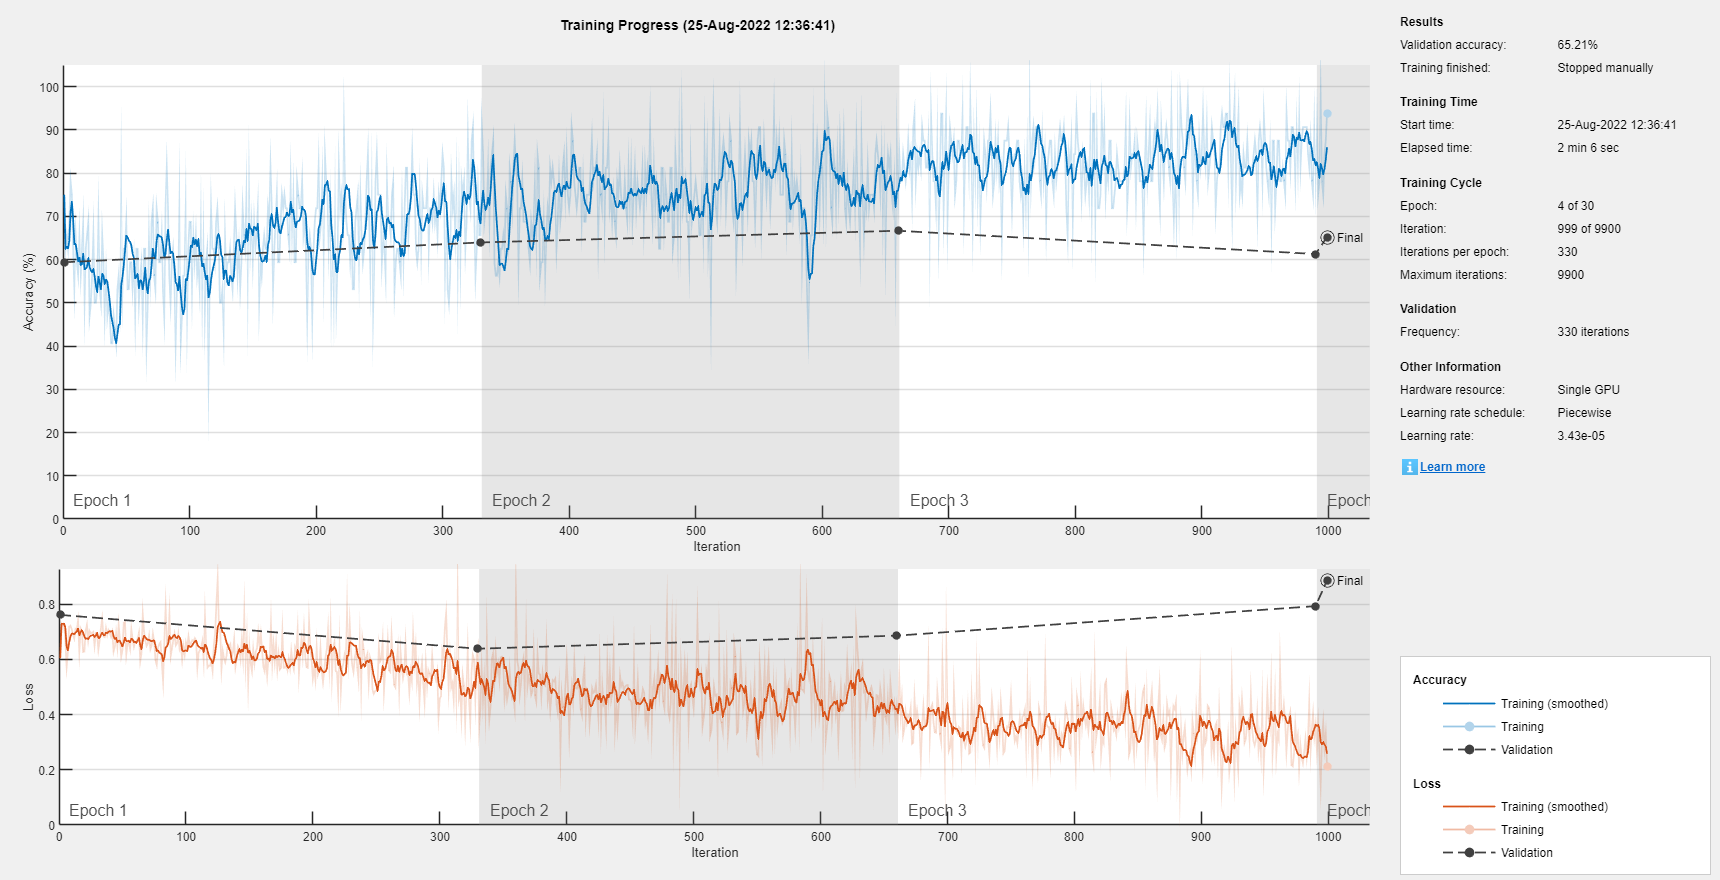

% remove saved nets from previous training
delete(checkpointPath + "/*");

% train network
[~, net_info] = trainNetwork(FeaturesPerSegTrain, trueLabelsPerSegTrain, lgraph, options);

load net (out of all nets yelded from current training) from epoch with best result (lowest validation error)

net_classification_CNN = extract_net_from_checkpoint(net_info, checkpointPath);

best epoch:
1


predict on train, val and test sets (probability [0,1]).

positive_indx = find(string(uniqueLabels) == "positive");
predLabelsPerSegTrain = predict(net_classification_CNN, FeaturesPerSegTrain, 'MiniBatchSize', miniBatchSize);
predLabelsPerSegTrain = predLabelsPerSegTrain(:, positive_indx);
predLabelsPerSegVal   = predict(net_classification_CNN, FeaturesPerSegVal, 'MiniBatchSize', miniBatchSize);
predLabelsPerSegVal   = predLabelsPerSegVal(:, positive_indx);
predLabelsPerSegTest  = predict(net_classification_CNN, FeaturesPerSegTest, 'MiniBatchSize', miniBatchSize);
predLabelsPerSegTest  = predLabelsPerSegTest(:, positive_indx);

change predictions and true labels from per spectrogram to per subject

[predLabelsPerSubjTrain, trueLabelsPerSubjTrain] = perSegment2perSubject(predLabelsPerSegTrain, trueLabelsPerSegTrain, adsSpecsTrain);
[predLabelsPerSubjVal, trueLabelsPerSubjVal] = perSegment2perSubject(predLabelsPerSegVal, trueLabelsPerSegVal, adsSpecsVal);
[predLabelsPerSubjTest, trueLabelsPerSubjTest] = perSegment2perSubject(predLabelsPerSegTest, trueLabelsPerSegTest, adsSpecsTest);

find best ROC thrshold on val set, and plot ROC curve

plot ROC curve and confusion matrix on test set.

display for train, val and test sets:

- ROC & AUC

- confusion matrix

- accuracy, UAR (unweighted average recall), F1 score, sensetivity, PPV, specificity

accuracy = (TP + TN) / (TP + TN + FP + FN)

UAR = (sensetivity + specificity) / 2

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

specificity = TN / (TN + FP)

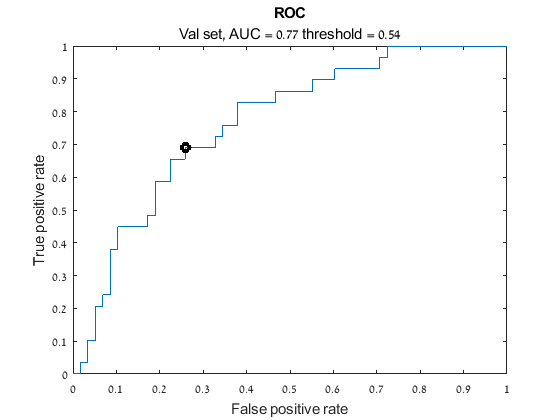

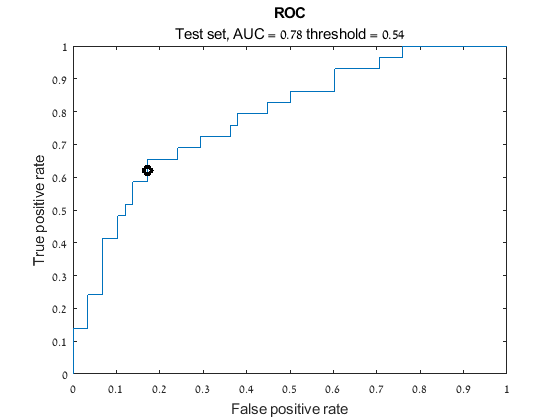

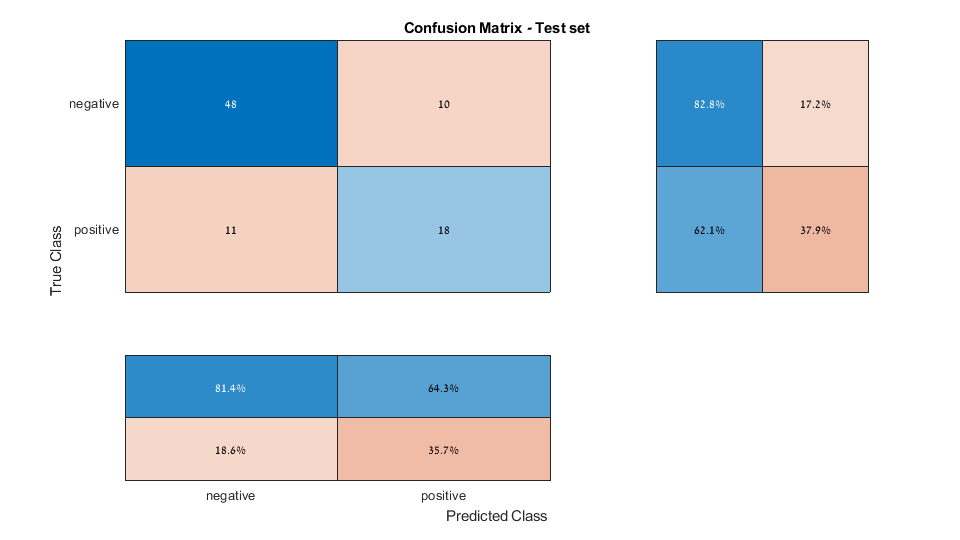

scores:
             accuracy [%]    UAR [%]    F1 [%]    sensitivity [%]    PPV [%]    specificity [%]
             ____________    _______    ______    _______________    _______    _______________

    train        84.9         85.5       79.4          87.2           72.8           83.7      
    val          71.3         70.7       61.5            69           55.6           72.4      
    test         75.9         72.4       63.2          62.1           64.3           82.8      



roc_threshold = 0.5; % choose threshold for ROC curve
set_threshold = "auto"; % define if to use manual threshold or auto decision

extract_scores_classification_CNN( ...
    {predLabelsPerSubjTrain predLabelsPerSubjVal predLabelsPerSubjTest}, ...
    {trueLabelsPerSubjTrain trueLabelsPerSubjVal trueLabelsPerSubjTest}, ...
    net_cnn_name, ...
    dataset_name, ...
    set_threshold, ...
    roc_threshold ...
    );